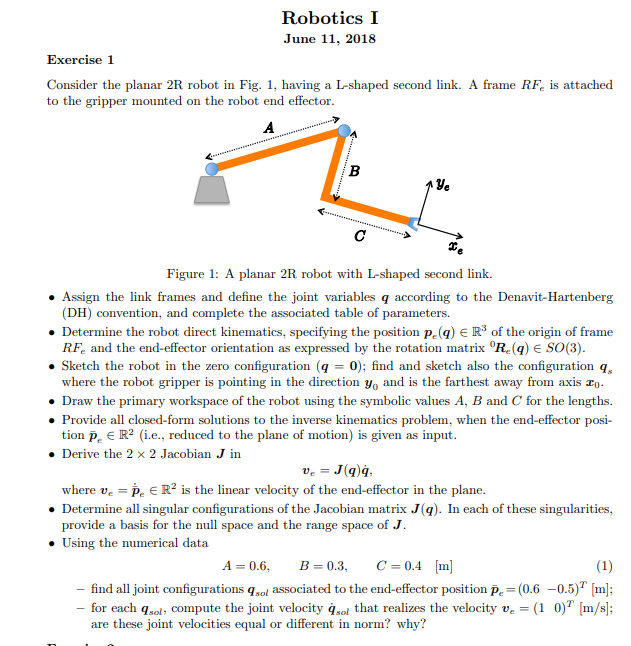

clear all, close all, clc
% A=sym( 'A','real');% B C D 
% B=sym( 'B','real');
% C=sym( 'C','real');
% D=sym( 'D','real');
% q=sym('q',[2,1],'real');
% A_=0.6;
% B_=0.3;
% C_=0.4;
% D_=sqrt(B_^2+C_^2);
% % syms alpha beta gamma
% alpha=sym( 'alpha','real');
% beta=sym( 'beta','real');
% gamma=sym( 'gamma','real');
% %[Rx Ry Rz] = getEulerRotationMatrices();
% [Rz, R_set] = getRotMatProduct('Z',0,[ beta]);
% a1=A
% a2=6
% dhTable=[0,A,0,q(1);
%          0,D,0,q(2)];
% De Luca's approach
% links = [
%     Revolute('alpha', 0, 'a', A_ ,'d', 0);
%     Revolute('alpha',  0, 'a', D_,'d', 0)
% 
%     ];
% c600 = SerialLink(links);
% c600.teach([0 0],'view','top')
% [T_total T_Partial R_total R_Partial P_total P_Partial] = getTransformationMatrix(dhTable, 'alpha');
% T_total %without translation
% Az=[[Rz 0]',0]';
% Az(end,end)=1;
% T_total=simplify(T_total*Az)% with beta translation
% %R_total=simplify(R_total*Rz)
% 
% p_e=T_total(1:3,4)
% p_e2=simplify(P_Partial{1}+R_Partial{1}*P_Partial{2})
% syms px real
% syms py real
% 
% pehat=[px py]'
% q_=solve(p_e2(1:2)==pehat,q, 'Real', true)
% Jredpe=jacobian(p_e2(1:2),q)
% detJ=simplify(det(Jredpe)) %%only when q2 is 0 or pi q1 doesn't matters
% q_singular=solve(detJ==0,q);
% [qsingular_,qsingular_names_,qsingular_tosolve2] =solvetoarray(q_singular,q);
% % null(Jredpe)
% pehat_=[0.6 -0.5]'
% parametershat=[pehat;A;D]
% parametershat_=[pehat_;A_;D_]
% [qdvarray,qdvnames_,vartosolve2] =solvetoarray(q_,q);
% digits(4)
% qdvarray_=vpa(subs(qdvarray,parametershat,parametershat_))
% vpa(qdvarray_*180/pi)
% q_d1_sol=inv(Jredpe)*[1,0]'
% q_d1_sola=vpa(subs(q_d1_sol,[A;D;q],[A_;D_;qdvarray_(:,2)]))
% % vpa(subs(q_.q1,parametershat,parametershat_)*180/pi)
% % vpa(subs(q_.q2,parametershat,parametershat_)*180/pi)


## exercise 2

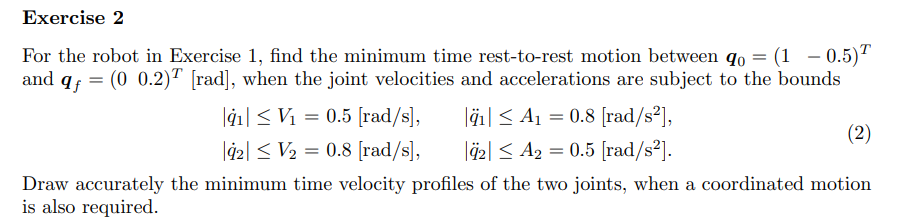

syms A1 T t t2nd

q0=[1,-0.5]';
qf=[0,0.2]';
deltaq=qf-q0

deltaq =    -1.0000
    0.7000


A1_=0.8

A1_ = 0.8000

V1_=0.5

V1_ = 0.5000

A2_=0.5

A2_ = 0.5000

V2_=0.8

V2_ = 0.8000

deltaq

deltaq =    -1.0000
    0.7000


L1_Criterio=V1_^2/A1_

L1_Criterio = 0.3125

L2_Criterio=V2_^2/A2_

L2_Criterio = 1.2800

## for q1 Bang Cost Bang profile

T1_=abs(deltaq(1))/V1_+V1_/A1_

T1_ = 2.6250

[qa_piece1,T_,Ts_] = BangcostBangPRofile(q0(1),qf(1),-V1_, -A1_)%A1_) colocar atención con el sentido de las trayectorias

$$qa\_piece1 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ 0 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ A_{1}\,\mathrm{Ts} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ A_{1}\,\mathrm{Ts}-A_{1}\,\left(\mathrm{Ts}-T+t\right) & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \sigma_{1}+1 & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ -\frac{A_{1}\,{\mathrm{Ts}}^{2}}{2}+A_{1}\,t\,\mathrm{Ts}+1 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -\frac{A_{1}\,T^{2}}{2}+A_{1}\,T\,\mathrm{Ts}+A_{1}\,T\,t-A_{1}\,{\mathrm{Ts}}^{2}-\sigma_{1}+1 & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{1}\,t^{2}}{2} \end{array}$$

$$qa\_piece2 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ 0 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ A_{1}\,\left(T-t\right) & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \sigma_{2}+1 & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1}\,t-\frac{{V_{1}}^{2}}{2\,A_{1}}+1 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ T\,V_{1}-\frac{A_{1}\,T^{2}}{2}-\sigma_{2}-\frac{{V_{1}}^{2}}{A_{1}}+A_{1}\,T\,t+1 & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{V_{1}+A_{1}\,t}{A_{1}}\\ \sigma_{2}=\frac{A_{1}\,t^{2}}{2} \end{array}$$

$$qa\_piece1 = \left(\begin{array}{c} \left\{ \begin{array}{cl} -0.8 & \text{ if }t\in \left[0.0,0.625\right)\\ 0.0 & \text{ if }t\in \left[0.625,2.0\right)\\ 0.8 & \text{ if }t\in \left[2.0,2.625\right] \end{array}\right.\\ \left\{ \begin{array}{cl} -0.8\,t & \text{ if }t\in \left[0.0,0.625\right)\\ -0.5 & \text{ if }t\in \left[0.625,2.0\right)\\ 0.8\,t-2.1 & \text{ if }t\in \left[2.0,2.625\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 1.0-0.4\,t^{2} & \text{ if }t\in \left[0.0,0.625\right)\\ 1.156-0.5\,t & \text{ if }t\in \left[0.625,2.0\right)\\ 0.4\,t^{2}-2.1\,t+2.756 & \text{ if }t\in \left[2.0,2.625\right] \end{array}\right. \end{array}\right)$$

T_ = 2.6250

Ts_ = 0.6250



%%in this case is no needed a cost midle part only bnag bang

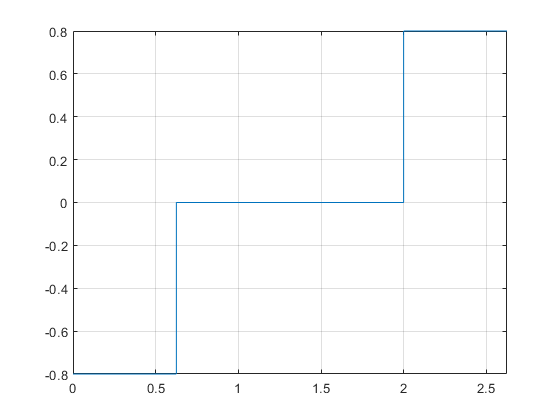

fplot(qa_piece1(1),[0,T_])
grid on

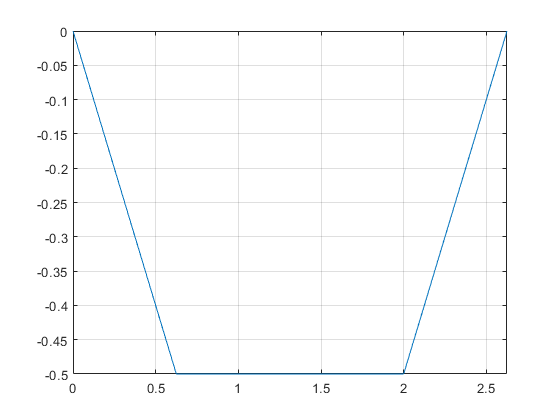

fplot(qa_piece1(2),[0,T_])
grid on

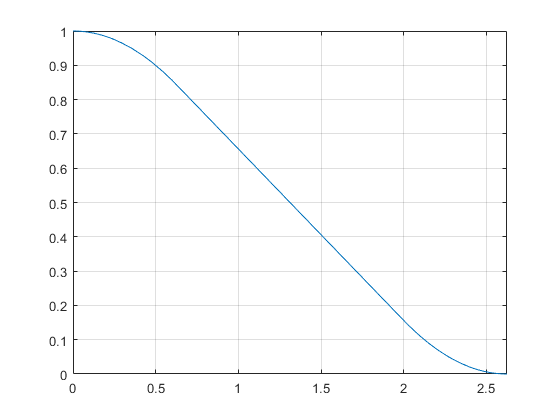

fplot(qa_piece1(3),[0,T_]) % There's a difference in the result.
grid on

## for q2 bang bang profile

T2_=sqrt(abs(deltaq(2))*4/A2_) % comoes el menor a max debe ser reajsutada

T2_ = 2.3664


A2max_=4*abs(deltaq(2))/(T1_^2)

A2max_ = 0.4063

[qa_piece2,T2red_,Ts_] = BangBangPRofile(q0(2),qf(2), A2max_)%A2_)

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2}-\frac{1}{2} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2}-\frac{1}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 0.40634920634920634920634920634921 & \text{ if }t\in \left[0.0,1.3125\right)\\ -0.40634920634920634920634920634921 & \text{ if }t\in \left[1.3125,2.625\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.40634920634920634920634920634921\,t & \text{ if }t\in \left[0.0,1.3125\right)\\ 1.0666666666666666666666666666667-0.40634920634920634920634920634921\,t & \text{ if }t\in \left[1.3125,2.625\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.2031746031746031746031746031746\,t^{2}-0.5 & \text{ if }t\in \left[0.0,1.3125\right)\\ 0.53333333333333333333333333333333\,t-0.2031746031746031746031746031746\,{\left(t-1.3125\right)}^{2}-0.85 & \text{ if }t\in \left[1.3125,2.625\right) \end{array}\right. \end{array}\right)$$

T2red_ = 2.6250

Ts_ = 0.5333



%%in this case is no needed a cost midle part only bnag bang

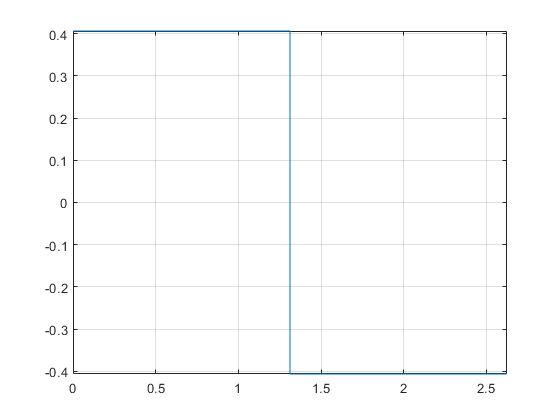

fplot(qa_piece2(1),[0,T1_])
grid on

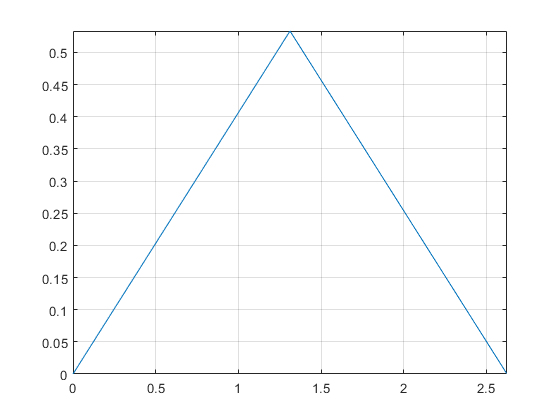

fplot(qa_piece2(2),[0,T1_])
grid on

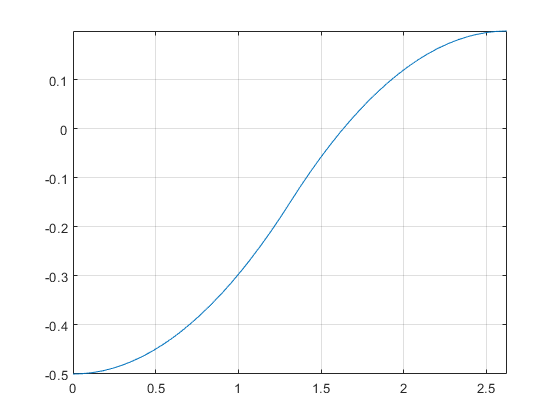

fplot(qa_piece2(3),[0,T1_]) % There's a difference in the result.
grid on